nx1 = 0 : 9;
nh1 = 0 : 9;

x = [ones(1, 5), zeros(1, 5)];
h_e1 = [1, -1, 3, 0, 1, zeros(1, 5)];
h_e2 = [0, 0, 1, -1, 3, 0, 1, zeros(1, 3)];

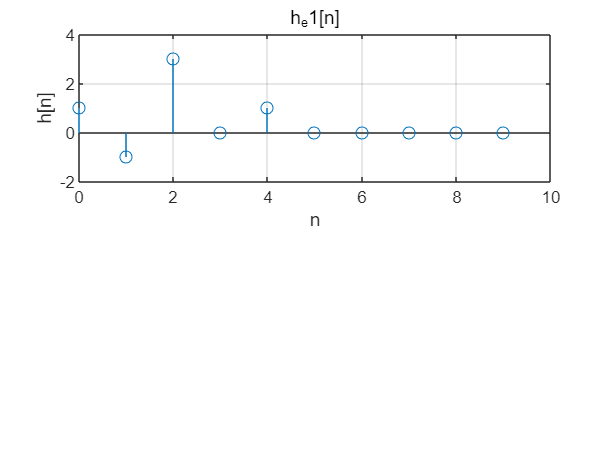

figure(1);
subplot(2, 1, 1);
stem(nh1, h_e1);
title("h_e1[n]");
xlabel("n")
ylabel("h[n]");
grid on;

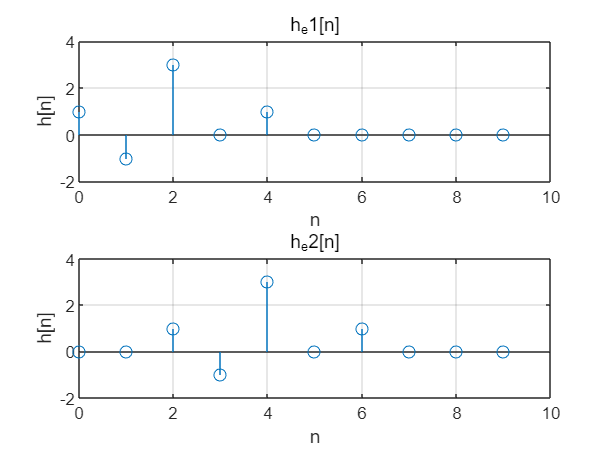

subplot(2, 1, 2);
stem(nh1, h_e2);
title("h_e2[n]");
xlabel("n")
ylabel("h[n]");
grid on;
hold on;

ny = nh1(1) + nx1(1) : nh1(end) + nx1(end);
y_e1_1 = conv(x, h_e1);
y_e1_2 = conv(h_e1, x);
y_e2_1 = conv(x, h_e2);
y_e2_2 = conv(h_e2, x);

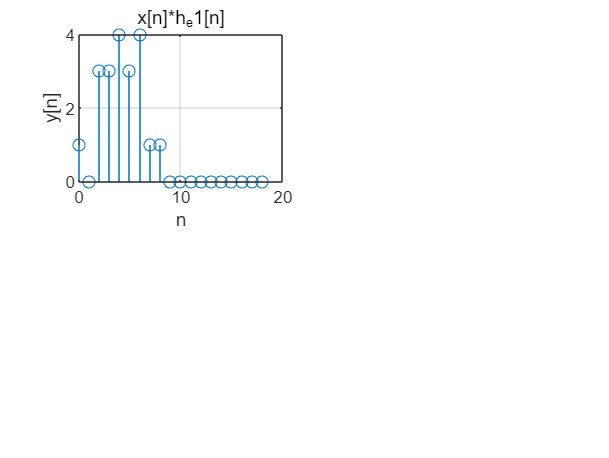

close all;
figure(2)
subplot(2, 2, 1);
stem(ny, y_e1_1);
title("x[n]*h_e1[n]");
xlabel("n")
ylabel("y[n]");
grid on;

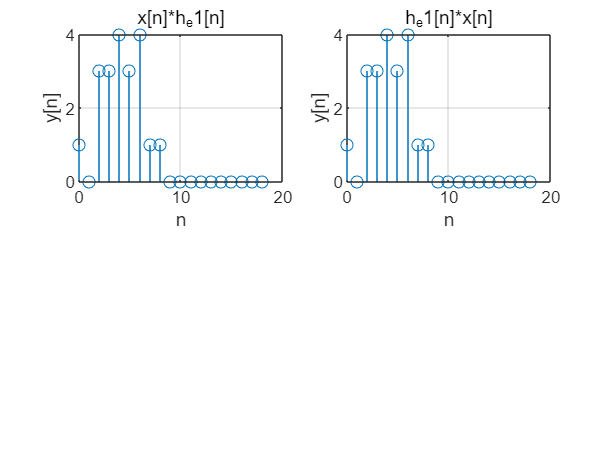

subplot(2, 2, 2);
stem(ny, y_e1_2);
title("h_e1[n]*x[n]");
xlabel("n")
ylabel("y[n]");
grid on;

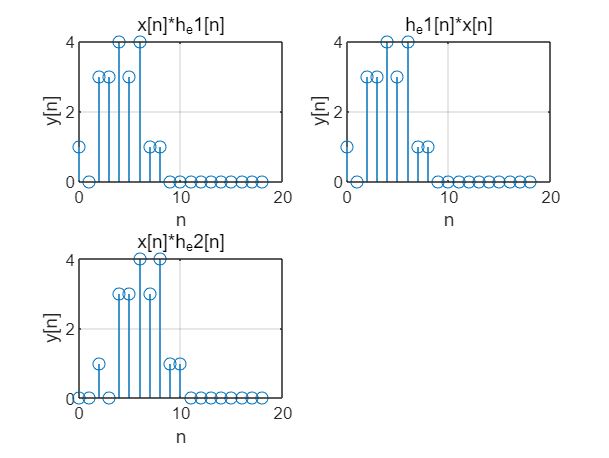

subplot(2, 2, 3);
stem(ny, y_e2_1);
title("x[n]*h_e2[n]");
xlabel("n")
ylabel("y[n]");
grid on;

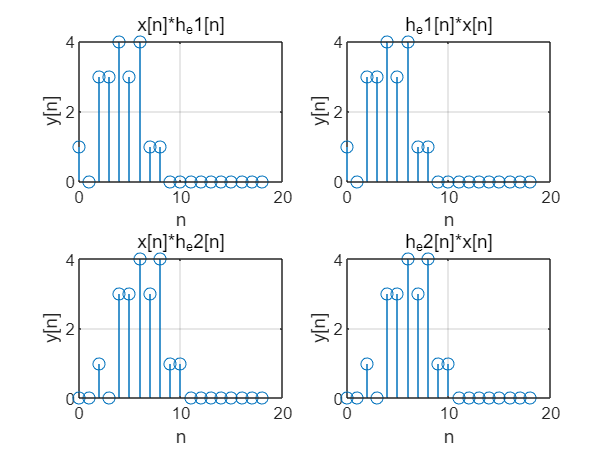

subplot(2, 2, 4);
stem(ny, y_e2_2);
title("h_e2[n]*x[n]");
xlabel("n")
ylabel("y[n]");
grid on;
hold on;

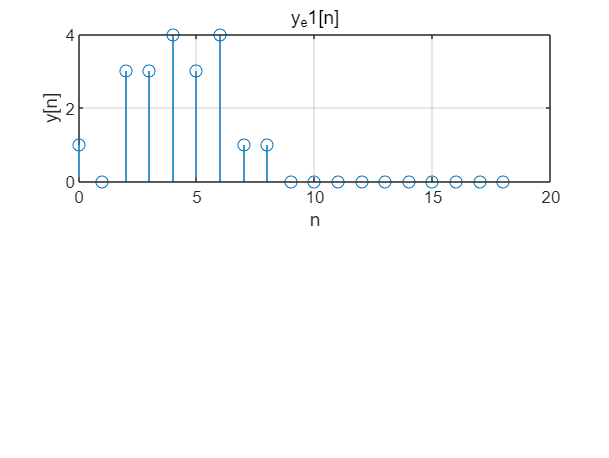

figure(3);
subplot(2, 1, 1);
stem(ny, y_e1_1);
title("y_e1[n]");
xlabel("n")
ylabel("y[n]");
grid on;

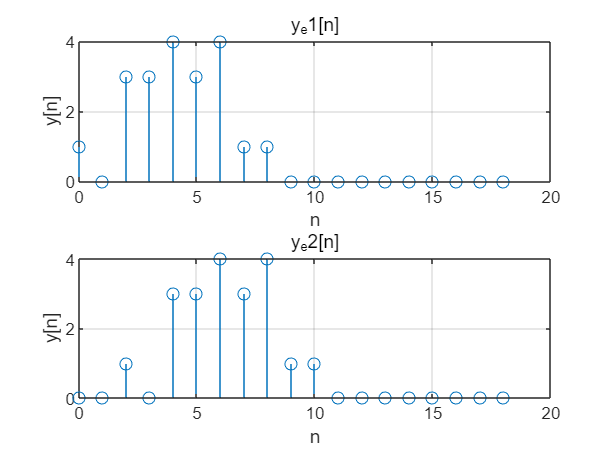

subplot(2, 1, 2);
stem(ny, y_e2_1);
title("y_e2[n]");
xlabel("n")
ylabel("y[n]");
grid on;